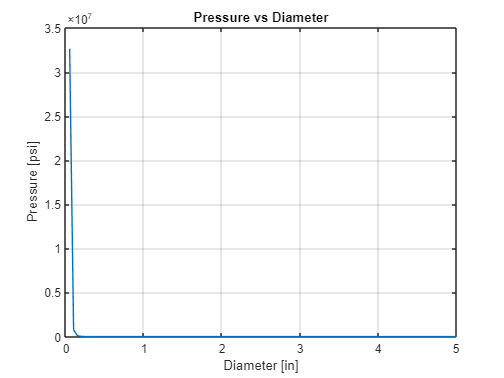

clear, clc

% Constants---------------------------------------------------------------
mdot = 2; %lbm/s
g = 32.2; % ft/s^2

% Inputs ---------------------------------------------------------------
rho = 71.843; % lbm/ft3
mu = 0.00013683; %lbm/ft*s
eps = 0.0018; % inches Commercial or Welded Steel

% Calculator ---------------------------------------------------------------

d = linspace(0,5,100); % inches
A = pi*(d/2).^2; % inches^2
V = mdot./(rho*A/144); % ft/s

Re = rho*V.*d*12/mu;

K = eps./d;

f = colebrook([Re],K);

L = 6; % ft

hf = f.*(L.*V.^2)./(d*2*g);

delP = rho*hf;


plot(d,delP)
title('Pressure vs Diameter')
xlabel('Diameter [in]')
ylabel('Pressure [psi]')
grid on